2020_04_03 SIM Simulation Code

This script will generate the optical transfer functions used in structured illumination microscopy. It will follow the notation described in Shao et al. Biophysical Journal 2008 (https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6). We will first be simulating the forward image generation process using an up-sampled (smaller pixel) code. Since the physical image generation process is continuous (e.g. not discritized), this is important to avoid artifacts later. Then we'll down-sample this data to replicate the process of observering on a continuous process on a discretized camera.

First, we will calculate the detection point spread function and optical transfer function using FFTs and the Debye approximation

%Define the image simulation parameters:
nx = 129; ny = 129; nz = 129; %Image dimensions
dx = 0.1; dy = 0.1; dz = 0.1; %Voxel dimensions
dkx=1/(nx*dx); dky=1/(ny*dy); dkz=1/(nz*dz); %Voxel dimensions in inverse space
forward_supersample=2;


Note that I use odd numbers for the image dimensions just so that the center will be at (0,0)

%Upsample when simulating the forward problem
nx_f=(nx-1)*forward_supersample+1; ny_f=(ny-1)*forward_supersample+1; nz_f=(nz-1)*forward_supersample+1;
% nx_f=(nx)*forward_supersample; ny_f=(ny)*forward_supersample; nz_f=(nz-1)*forward_supersample+1;
dx_f=dx/forward_supersample; dy_f=dy/forward_supersample; dz_f=dz/forward_supersample;
dkx_f=1/(nx_f*dx_f); dky_f=1/(ny_f*dy_f); dkz_f=1/(nz_f*dz_f);

%Define detection simulation parameters:
NA_det = 1.0; %Detection objective NA
F_det = 8000; %Detection objective focal length (in microns)
nimm = 1.33; %Refractive index of immersion media
wvl_em = 0.605; %Emission wavelength (in microns)
zern_Num = [5];
zern_Weight = [0];


These next parameters are used for simulating alignment errors/tolerances. They are all zero for this script.

offset = [0,0]; %Offset of the input/output beam from the objective axis
tip_tilt = [0,0]; %Angle of the input/output beam from the objective axis
piston = 0; %Piston (phase delay/advance) of the input/output beam

%Run the code to compute the forward detection PSF
[dPSFa_f,dPSFi_f,dOTF_f,dkx_f,dky_f,dkz_f]=calc_FFT_detPSF_WRL_2020_04_02_withZern(NA_det,F_det,nimm,wvl_em,nx_f,ny_f,nz_f,dx_f,dy_f,dz_f,offset,tip_tilt,piston,zern_Num,zern_Weight);

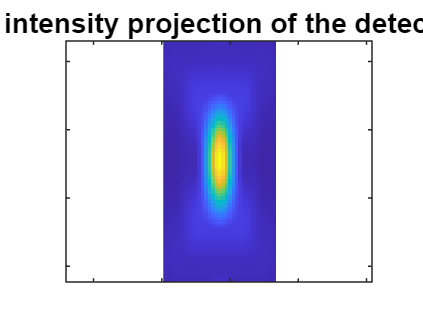

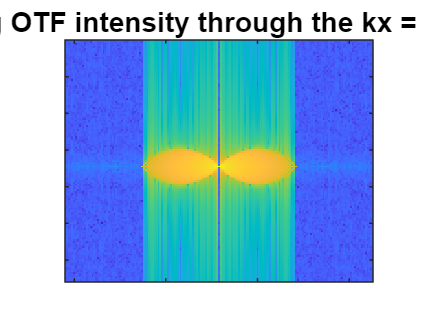

%Display the results for the detection PSF and OTF
projection = "XZ";
if projection =='XY'
figure
imagesc(squeeze(max(dPSFi_f((nx_f+1)/2-16:(nx_f+1)/2+16,(ny_f+1)/2-16:(ny_f+1)/2+16,:),[],3)))
axis equal
title('XY max intensity projection of the detection PSF')
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])
figure
imagesc(squeeze(log(abs(dOTF_f(:,:,(nx_f+1)/2)))))
title('XY log OTF intensity through the kz = 0 plane')
axis equal
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])
xlim([45 213])
ylim([60 192])
end
if projection =='XZ'
imagesc(imrotate(squeeze(max(dPSFi_f((nx_f+1)/2-16:(nx_f+1)/2+16,(ny_f+1)/2-16:(ny_f+1)/2+16,:),[],1)),90))
axis equal
title('XZ max intensity projection of the detection PSF')
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])
xlim([-28.0 61.6])
ylim([94.0 164.6])
figure
imagesc(imrotate(squeeze(log(abs(dOTF_f((nx_f+1)/2,:,:)))),90))
title('XZ log OTF intensity through the kx = 0 plane')
axis equal
set(gca,'YTickLabel',[])
set(gca,'XTickLabel',[])
xlim([45 213])
ylim([60 192])
end

Next, we need to generate the illumination pattern that excites the fluorescence in the specimen.

%Define excitation simulation parameters:
NA_ext_max = 0.55; %Max excitation NA
NA_ext_min = 0.50; %Min excitation NA
NA_ext_cent = 0.525; %Center excitation NA (where the beams will be centered on the rear pupil)
F_ext = 7170; %Excitation objective focal length (in microns)
wvl_ext = 0.560; %Excitation wavelength (in microns)
n_phases = 5; %Number of phases that will be used for illumination
ext_pol = 'x'; %Polarization of the excitation beam (can be 'x' or 'y')

We need to generate one illumination pattern for each "phase" of the SIM imaging. These are just the same patterns, but shifted laterally by a fraction of the pattern period. Note, that different phases will then have a phase ramp (tilt) in the excitation OTF.

%Generate HEX illumination patterns with different phases spaced equally
%between 0 and 2pi
for ii=0:n_phases-1
    eval(['[ePSFa_',num2str(ii),',ePSFi_',num2str(ii),',eOTF_',num2str(ii),',xx,yy,zz,kx,ky,kz,PW_scaled]=calc_FFT_extPSF_HEX_2017_03_28([NA_ext_max,NA_ext_min,NA_ext_cent],F_ext,nimm,wvl_ext,nx_f,ny_f,nz_f,dx_f,dy_f,dz_f,offset,tip_tilt,piston,''x'',(',num2str(ii),'*2*pi/5));']);
    eval(['ePSFi_',num2str(ii),'=ePSFi_',num2str(ii),'./sum(ePSFi_',num2str(ii),'(:));']); %Normalize PSF intensity to 1
    
    %Rotate into the proper orientation for excitation objective (perpendicular to detection obj) and adjust vector
    %components
    eval(['ePSFa_',num2str(ii),'=flipdim(permute(ePSFa_',num2str(ii),',[1,4,3,2]),4);']);
    eval(['ePSFa_',num2str(ii),'=cat(1,ePSFa_',num2str(ii),'(1,:,:,:),ePSFa_',num2str(ii),'(3,:,:,:),-ePSFa_',num2str(ii),'(2,:,:,:));']);
    eval(['ePSFi_',num2str(ii),'=flipdim(permute(ePSFi_',num2str(ii),',[1,4,3,2]),4);']);
    eval(['ePSFi_',num2str(ii),'=squeeze(ePSFi_',num2str(ii),'*1e9);']); %Scale total PSF intensity to 1e9
    eval(['eOTF_',num2str(ii),'=fftshift(fftn(ifftshift(ePSFi_',num2str(ii),')));']);
end

%Display the results for the excitation PSFs and OTFs
phase = 2

phase = 2

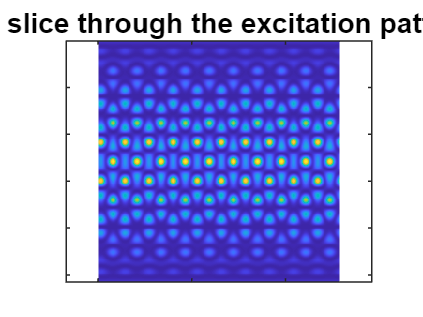

    eval(['imagesc(imrotate(squeeze((ePSFi_',num2str(phase),'((nx_f+1)/2,:,:))),90))'])
    axis equal
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('XZ slice through the excitation pattern')

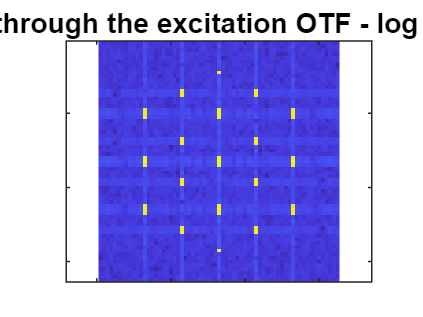

    figure
    eval(['imagesc(imrotate(squeeze(log(abs(eOTF_',num2str(phase),'((nx_f+1)/2,(ny_f+1)/2-32:(ny_f+1)/2+32,(nz_f+1)/2-32:(nz_f+1)/2+32)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('XZ slice through the excitation OTF - log amplitude')
    axis equal

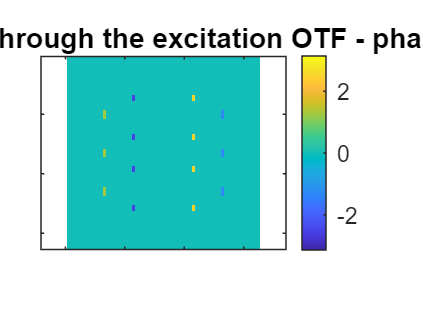

    figure
    mask=abs(eOTF_0)>1;
    mask = mask((nx_f+1)/2,(ny_f+1)/2-32:(ny_f+1)/2+32,(nz_f+1)/2-32:(nz_f+1)/2+32);
    eval(['imagesc(imrotate(squeeze((mask.*angle(eOTF_',num2str(phase),'((nx_f+1)/2,(ny_f+1)/2-32:(ny_f+1)/2+32,(nz_f+1)/2-32:(nz_f+1)/2+32)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    axis equal
    colorbar
    caxis([-pi pi])
    title('XZ slice through the excitation OTF - phase')

Now that we have both the excitation and detection PSFs, we have to simulate the imaging process and generate overall point spread functions for each excitation pattern. Naively, we might think this is just a multiplicatoin of the two PSFs (convolution of the OTFs), but this isn't the case. At the focal plane, the image will be the multiplication of the sample distribution with the laterally distributed illumination pattern, then convolved with the detection point spread function. However, as we scan axially, the illumination remains fixed relative to the detection focal plane. The net result of this is that axial modulation in the excitation pattern multiplies the detection PSF, not the sample data. So, in order to faithfully reproduce the 3D imaging process, we have to split the illumination pattern up into lateral and axial components and treat these separately. 

Moving forward, it is useful to adopt the notation from Gustafsson et al:

*"The observed data D(****r****) is the convolution of the emitting object E(****r****) and the (detection) PSF H(****r****)"*

*D*(**r**)=(*E*⊗*H*)(**r**)     **(1)**

In Fourier space, equation 1 becomes:

*D*˜(**k**)=*E*˜(**k**)*H*˜(**k**)=*E*˜(**k**)*O*(**k**)     **(1*)**

where *O*(**k**) = *H*˜(**k**) is the optical transfer function of the detection objective.

The "emitting object" E(**r**) is actually the product of the illumination pattern and the underlying fluorescent probe distribution.

*E*(**r**)=*S*(**r**) x *I*(**r**)    **(2)**

In Fourier space, equation 2 becomes:

*E*˜(**k**)=(*S*˜⊗*I*˜)(**k**) **(2*)**

This next section from the paper is key:

*"First, the illumination pattern, I, should be a sum of a finite number of  components, each of which is separable into an axial and a lateral function"*

*I*(**r**xy,*z*)=∑*I_*m(*z*)*J_*m(**r**xy) **(3)**

where rxy is the lateral coordinates, I_m(z) is the axial component and J_m(**r**xy) is the lateral component.

*"Second, each of those lateral functions Jm should be a simple harmonic wave (i.e., contain only a single spatial frequency). Thirdly, one of two conditions should be met: either the axial  functions Im are also purely harmonic, or, when the  three-dimensional data are acquired as a sequence of two-dimensional  images with different focus, the illumination pattern is maintained  fixed in relation to the focal plane of the microscope, not in relation  to the object. The latter condition is what we will discuss in this  article, because it allows a broader choice of the axial function Im."*

* "The significance of the last condition can be understood by first  considering the alternative arrangement where the illumination pattern  is kept fixed in relation to the object during acquisition. In that  case, Eqs. *[*(1)*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq1)*, *[*(2)*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq2)*, *[*(3)*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq3)* apply directly and lead to the following convolution integral for the measured data:"*

*D*(**r**)=(*H*⊗*E*)(**r**)=[*H*⊗(*S* *I*)](**r**)  =∑m∫*H*(**r**−**r**′)*S*(**r**′)*I_*m(*z*′)*J_*m(**r**′xy)d**r**′.    **(4)**

*"In the above integral, primed coordinates ****r****′ refer to the specimen reference frame, unprimed coordinates ****r**** refer to the data set reference frame (in particular, the axial coordinate z refers to the physical displacement of the specimen slide relative to the objective lens), and the difference coordinates, ****r****–****r****′, refer to the reference frame of the objective lens. It is seen that the point spread function H depends on the difference coordinates ****r****–****r****′. If we now consider holding the light pattern fixed relative to the  objective lens's focal plane during focusing, that means that Im will depend not on the specimen-frame's primed coordinate z′ but rather on the objective-lens-frame's difference coordinate z–z′, the same coordinate as the point spread function H depends on. **Therefore the axial part of each illumination component multiplies the point spread function, not the object S, in the convolution integral**:"*

*D*(**r**) =∑m∫*H*(**r**−**r**′)*I*m(*z*−*z*′)*S*(**r**′)*J*m(**r**′xy)*d***r**′  **(5)**

       =∑m[(*H* *I*m)⊗(*S* *J*m)](**r**)

So, for our code so far, dPSFi_f = *H*(**r**), dOTF_f = *O*(**k**) = *H*˜(**k**), ePSFi_# = I(**r**), and eOTF_# = I˜(**k**). The excitation patterns I(**r**), and I˜(**k**) can each be expressed as a sum of products between lateral and axial components: 

*I*(**r**xy,*z*)=∑*I_*m(*z*)*J_*m(**r**xy) **(3) **

This can also be expressed as a sum of convolutions in frequency space:

*I*˜(**r**xy,*z*)=∑*I*˜*_*m(*z*)⊗*J*˜*_*m(**r**xy) **(3*) **

which we will use to simulate the forward imaging process.

Graphically, this looks like this:

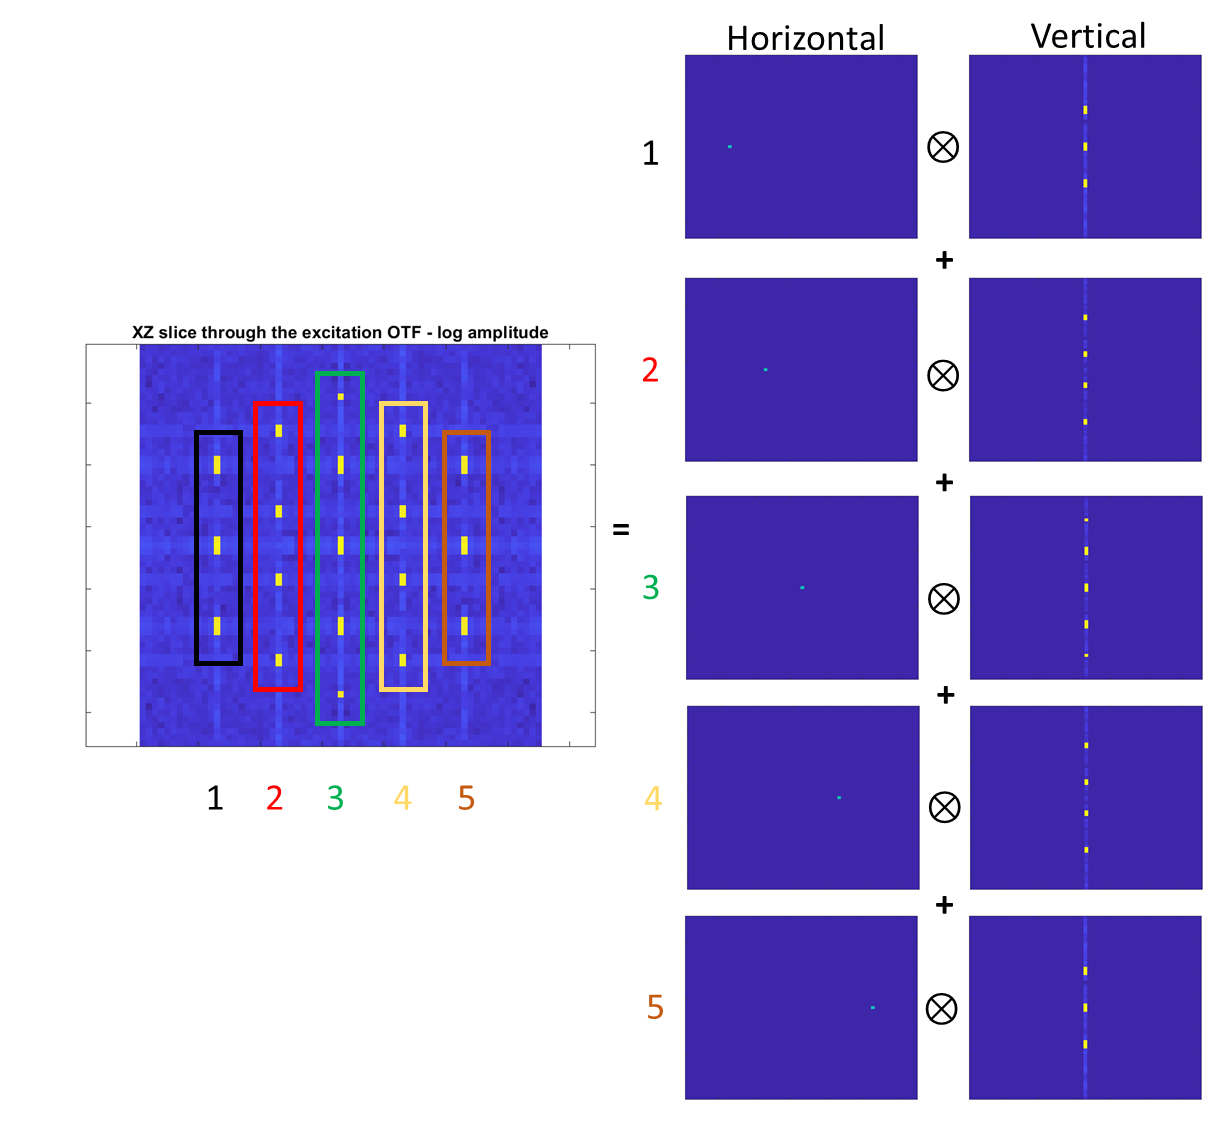

For now, we'll assume that our data is just a delta function (single voxel). This will then be used to simulate the transfer functions used for reconstruction.

%Generate the distribution of fluorophores at the sample
Sample=zeros(nx_f,ny_f,nz_f);
Sample((nx_f+1)/2,(ny_f+1)/2,(nz_f+1)/2)=1;

Now, we need to determine the number of information components present in the illuminaton pattern. This is equal to the number of "difference" vectors between spots in the excitation OTF. These can further be split into lateral difference vectors and axial difference vectors. 

%Determine the number of difference vectors in the excitation OTF
PW_scaled_reorder=[PW_scaled(:,3),PW_scaled(:,1),PW_scaled(:,2)];
[rows,~]=size(PW_scaled_reorder);
tt=1;
for pp=1:rows
    for rr=1:rows
        diff_vec(tt,:)=PW_scaled_reorder(pp,:)-PW_scaled_reorder(rr,:);
        tt=tt+1;
    end
end
diff_vec=round(diff_vec*1000)/1000;
diff_vec_unique=unique(diff_vec,'rows');
diff_vec_lateral=unique(diff_vec(:,1:2),'rows');

[num_information_comps,~]=size(diff_vec);
[num2str(num_information_comps),' total information components']

ans = '36 total information components'


[num_lat_order,~]=size(diff_vec_lateral);
[num2str(num_lat_order),' lateral information components']

ans = '5 lateral information components'

Next, we need to determine where the lateral information components are in frequency space for our excitation OTF. This will allow us to separate each OTF into a sum of lateral and axial components.

%For forward simulations, need to find discrete peaks in the OTF centered
%on pixels, actual reconstruction will use theoretical difference vectors
%based of wave vectors
ind_h=find(squeeze(sum(sum(abs(eOTF_0),1),3))>1e3); %Find center peaks of horizontal information components

Then, we separately apply the vertical and lateral components of the excitation PSF to our sample to get what the overall point spread function is for each phase of excitation pattern. This is simulating the "forward" process of image generation.


for ii=0:n_phases-1
    %Initialize separated information components for illumination
    SJ=zeros(nx_f,ny_f,nz_f); %Data times lateral frequency components of illumination
    HI=zeros(nx_f,ny_f,nz_f); %PSF times axial frequency components of illumination
    Dr=zeros(nx_f,ny_f,nz_f); %Acquired image data
    
    %For this step, lateral orders go from - to + (e.g. m2,m1,0,p1,p2) for 5 lateral
    %orders.  Note that this is different from the order of components
    %after applying the separation matrix later when recovering
    ['Computing image for illumination phase ',num2str(ii)]
    for kk=1:num_lat_order
        ['Computing lateral order ',num2str(kk),' of ',num2str(num_lat_order)]
        eOTF_h=zeros(nx_f,ny_f,nz_f); %Horizontal information component
        eOTF_v=zeros(nx_f,ny_f,nz_f); %Vertical information component
        
        eOTF_h((nx_f+1)/2,ind_h(kk),(nz_f+1)/2)=1;
        eval(['eOTF_v(',num2str((nx_f+1)/2),',',num2str((ny_f+1)/2),',:)=eOTF_',num2str(ii),'(',num2str((nx_f+1)/2),',',num2str(ind_h(kk)),',:);'])
        SJ=Sample.*squeeze(fftshift(ifftn(ifftshift(eOTF_h)))); %Sample times the horizontal information component
        HI=dPSFi_f.*squeeze(fftshift(ifftn(ifftshift(eOTF_v))));%PSF times the vertical information component
        Dr=Dr+fftshift(ifftn(ifftshift(fftshift(fftn(ifftshift(HI))).*fftshift(fftn(ifftshift(SJ)))))); %Combined data according to eqn 5 above
    end
    
    Dk=fftshift(fftn(ifftshift(Dr)));
    eval(['Dr_',num2str(ii),'=Dr;']);
    eval(['Dk_',num2str(ii),'=Dk;']);
end

ans = 'Computing image for illumination phase 0'

ans = 'Computing lateral order 1 of 5'

ans = 'Computing lateral order 2 of 5'

ans = 'Computing lateral order 3 of 5'

ans = 'Computing lateral order 4 of 5'

ans = 'Computing lateral order 5 of 5'

ans = 'Computing image for illumination phase 1'

ans = 'Computing lateral order 1 of 5'

ans = 'Computing lateral order 2 of 5'

ans = 'Computing lateral order 3 of 5'

ans = 'Computing lateral order 4 of 5'

ans = 'Computing lateral order 5 of 5'

ans = 'Computing image for illumination phase 2'

ans = 'Computing lateral order 1 of 5'

ans = 'Computing lateral order 2 of 5'

ans = 'Computing lateral order 3 of 5'

ans = 'Computing lateral order 4 of 5'

ans = 'Computing lateral order 5 of 5'

ans = 'Computing image for illumination phase 3'

ans = 'Computing lateral order 1 of 5'

ans = 'Computing lateral order 2 of 5'

ans = 'Computing lateral order 3 of 5'

ans = 'Computing lateral order 4 of 5'

ans = 'Computing lateral order 5 of 5'

ans = 'Computing image for illumination phase 4'

ans = 'Computing lateral order 1 of 5'

ans = 'Computing lateral order 2 of 5'

ans = 'Computing lateral order 3 of 5'

ans = 'Computing lateral order 4 of 5'

ans = 'Computing lateral order 5 of 5'

Now, we down sample the simulated data to represent experimentally acquired voxel sizes. This is done by cropping the image in frequency space. For this, Dr is the real-space representation of the data and Dk is the frequency space representation.

for ii=0:n_phases-1
    eval(['Dk_',num2str(ii),'=Dk_',num2str(ii),'((nx_f+1)/2-(nx-1)/2:(nx_f+1)/2+(nx-1)/2,(ny_f+1)/2-(ny-1)/2:(ny_f+1)/2+(ny-1)/2,(nz_f+1)/2-(nz-1)/2:(nz_f+1)/2+(nz-1)/2);']);
    eval(['Dr_',num2str(ii),'=fftshift(ifftn(ifftshift(Dk_',num2str(ii),')));'])
end

%Display the results for the overall Dr and Dk of the data
viewpoint = "XY"

viewpoint = "XY"

phase = 0

phase = 0

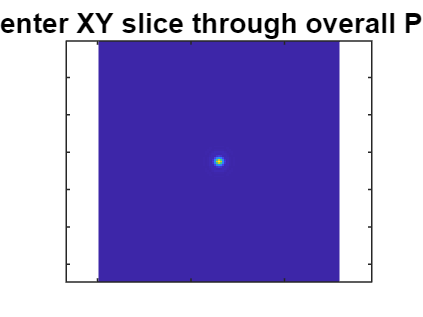

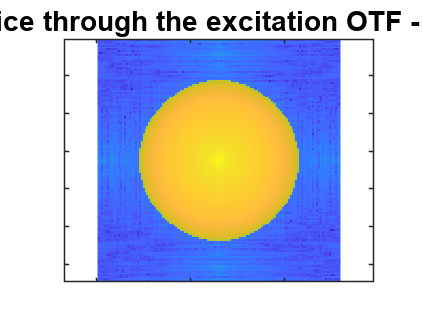

if viewpoint == 'XY'
    eval(['imagesc(imrotate(squeeze(abs((Dr_',num2str(phase),'(:,:,(nz+1)/2)))),0))'])
    axis equal
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('Center XY slice through overall PSF')
    figure
    eval(['imagesc(imrotate(squeeze(log(abs(Dk_',num2str(phase),'((nx+1)/2-64:(nx+1)/2+64,(ny+1)/2-64:(ny+1)/2+64,(nz+1)/2)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('Center XY slice through the excitation OTF - log amplitude')
    axis equal 
end

if viewpoint == 'XZ'
    eval(['imagesc(imrotate(squeeze(abs((Dr_',num2str(phase),'((nx+1)/2,:,:)))),90))'])
    axis equal
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('Center XZ slice through the overall PSF')
    figure
    eval(['imagesc(imrotate(squeeze(log(abs(Dk_',num2str(phase),'((nx+1)/2,(ny+1)/2-64:(ny+1)/2+64,(nz+1)/2-64:(nz+1)/2+64)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title('Center XZ slice through the excitation OTF - log amplitude')
    axis equal
end

The data above represents what we'd observe on the camera when taking our 3D image stacks. This is the superposition of shifted information components that have been down-modulated and are now all overlayed within the pass band of the microscope. Since our data was just a delta function, Dr and Dk in this sense are our combined PSF and OTFs recorded for each phase of illumination. To generate the super-resolved image, we first need to separate the information components present in each Dr/Dk, and then shift them back to their appropriate location in frequency space. Note that the axial resolution improvement has already been applied (since these components modified the PSF). But, there is not yet any lateral resolution improvement since we haven't shifted these in frequency space. We'll deal with the separation part first. 

*"It was assumed above that J_m is a simple harmonic:*

*J_*m(**r**xy)=*exp(*i(2*π***p_**m⋅**r**xy+*φ_*m))     **(7) **

*which implies that J˜m(****k****xy)=δ(****k****xy−****p_****m)exp(iφ_m). Substituted into Eq. *[*6*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq6)*, this implies that the observed data can be written as*

*D*˜(**k**)=∑*D*˜_m(**k**)=∑*O_*m(**k**)*exp(*i*φ_*m*S*˜(**k**−**p**_m))    **(8) **

*a sum of a finite number of copies of the object information S˜, each moved laterally in reciprocal space by a distance ****p_****m, filtered (and band-limited) by a transfer function Om, and phase-shifted by a phase φm. **In summary, each lateral frequency component m of the illumination structure corresponds to a separate optical transfer function Om, which is given by a convolution of the conventional detection OTF with the axial illumination structure of the mth pattern component, and applies to a component of object information  that has been translated in reciprocal space by the lateral wave vector ****p_****m of that pattern component**..."*

*"**As seen in Eq. *[*8*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq8)*, a single raw data image is a sum of several different information components, one for each index m. To restore the data, these information components must be separated**.  This can be done by acquiring additional data sets with different known  values of the phases φm. Changing the phase values by phase shifts δφm alters the coefficients eiφm in Eq. *[*8*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq8)* from eiφm0 to ei(φm0+δφm), leading to a linearly independent combination of the unknown  information components. Each phase-shifted image thus supplies one  independent linear equation in N unknowns (where N is the number of frequency components in Eq. *[*8*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq8)*). If data are acquired with at least N different phases, the number of equations is at least equal to the number of unknowns, allowing the N information components to be separated by applying a simple N×N matrix."*

*"**the measured data gains new (i.e., normally unobservable) information in two ways: the support of each transfer function Om is extended axially, compared to the conventional OTF O, through the convolution with the axial function I˜_m; and the translation by m****p**** moves new information laterally into the support of O_m**.*

*Because the O_m and ****p_****m are known, the separated information components can be computationally moved back (by a distance ****p_****m) to their true positions in reciprocal space, recombined into a single  extended-resolution data set, and retransformed to real space."*

Now we'll separte the information components within our image. Since this script is just for generating the transfer functions (i.e. OTFs for each lateral information component), we'll deal with shifting them to their appropriate locations in frequency space in another script. The key for this part is that our observed OTF is a linear combination of the sample information multiplied by 5 OTF information components at every pixel. 

From the text: 

*"In practice, the situation is usually simplified further in several  ways. A physical light intensity is a real-valued function; the  exponentials in Eq. *[*7*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq7)* must therefore occur in pairs with opposite ****p****m, corresponding to information from symmetrically located regions of reciprocal space. Because the Fourier transform a˜(****k****) of any real-valued function a(****r****) (such as the object structure) has the symmetry property that a˜(−****k****) is the complex conjugate of a˜(****k****), only one information component from each such pair has to be  calculated; the values within the other component follow by symmetry.  Secondly, if the set of different lateral spatial frequencies ****p****m of the illumination pattern is, in fact, the fundamental frequency and  harmonics of a periodic pattern, then all the spatial frequencies are  multiples of the fundamental: ****p****m = m****p****. If, furthermore, the phase-shifting of the illumination takes place by  spatially translating a rigid pattern, then the phase-shifts δφm are also multiples of a fundamental phase-shift: δφm = mδφ. For patterns with reflection symmetry, the same applies to the starting phases, φm0 = mφ0, and thus for the total phase: φm = mφ. In this situation, which was the case in our experiments, we can rewrite Eq. *[*8*](https://www.cell.com/biophysj/fulltext/S0006-3495(08)70360-6#eq8)* as"*

*D*˜(**k**)=∑*O_*m(**k**)*exp(*im*φ)S*˜(**k**−*m***p**).    **(9)**

Thus the observed Dk is a sum (over m = -2,-1,0,1,2) orders of the order-specific OTFs, a phase shift and the sample frequency content which has been shifted in frequency space into the observable pass-band. For this script, the "sample" is just a delta function and thus its Fourier transform *S*˜ = 1 everywhere, it will drop out of equation 9. Now, our observed Dk is just a linear combination of the order-specific OTFs, each with some applied phase shift. Since we acquired a series of images under different illumination phases, we can re-express (extract) this information by inverting a linear system of equations that maps the illumination phase to the OTF phase for each order at each pixel.

In otherwords, the value of every pixel of Dk can be expressed as a forward problem that looks like this:

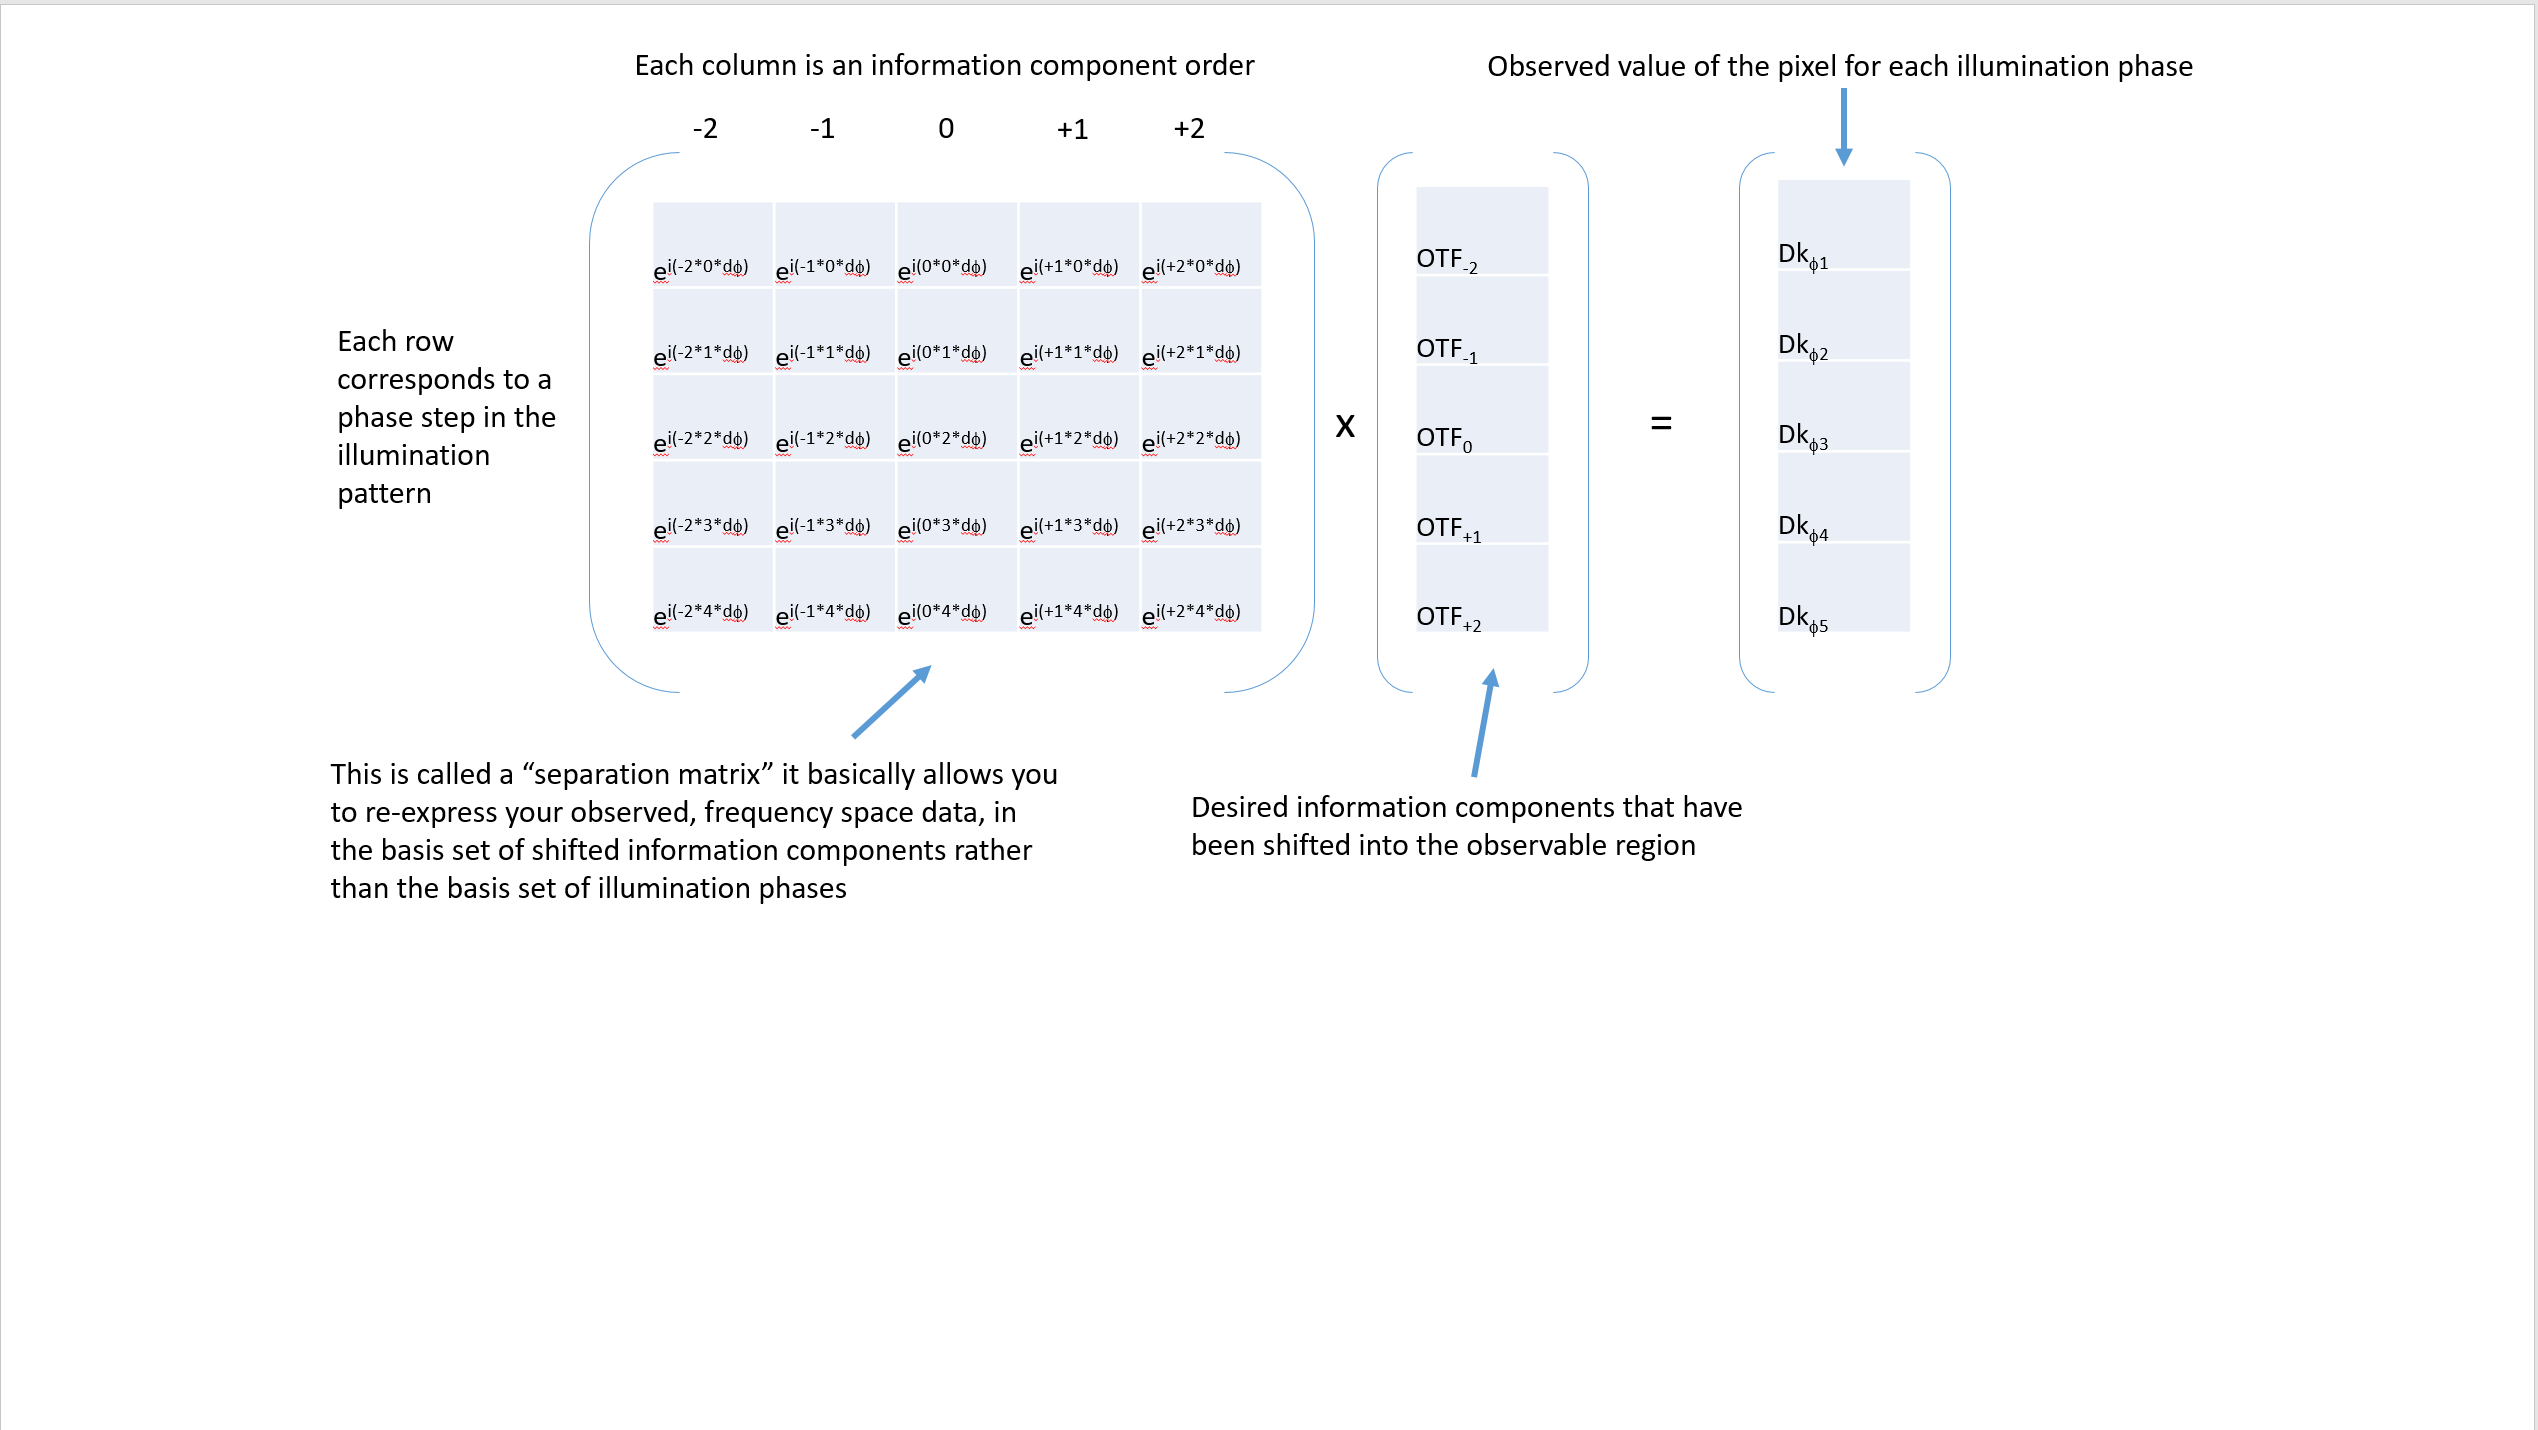

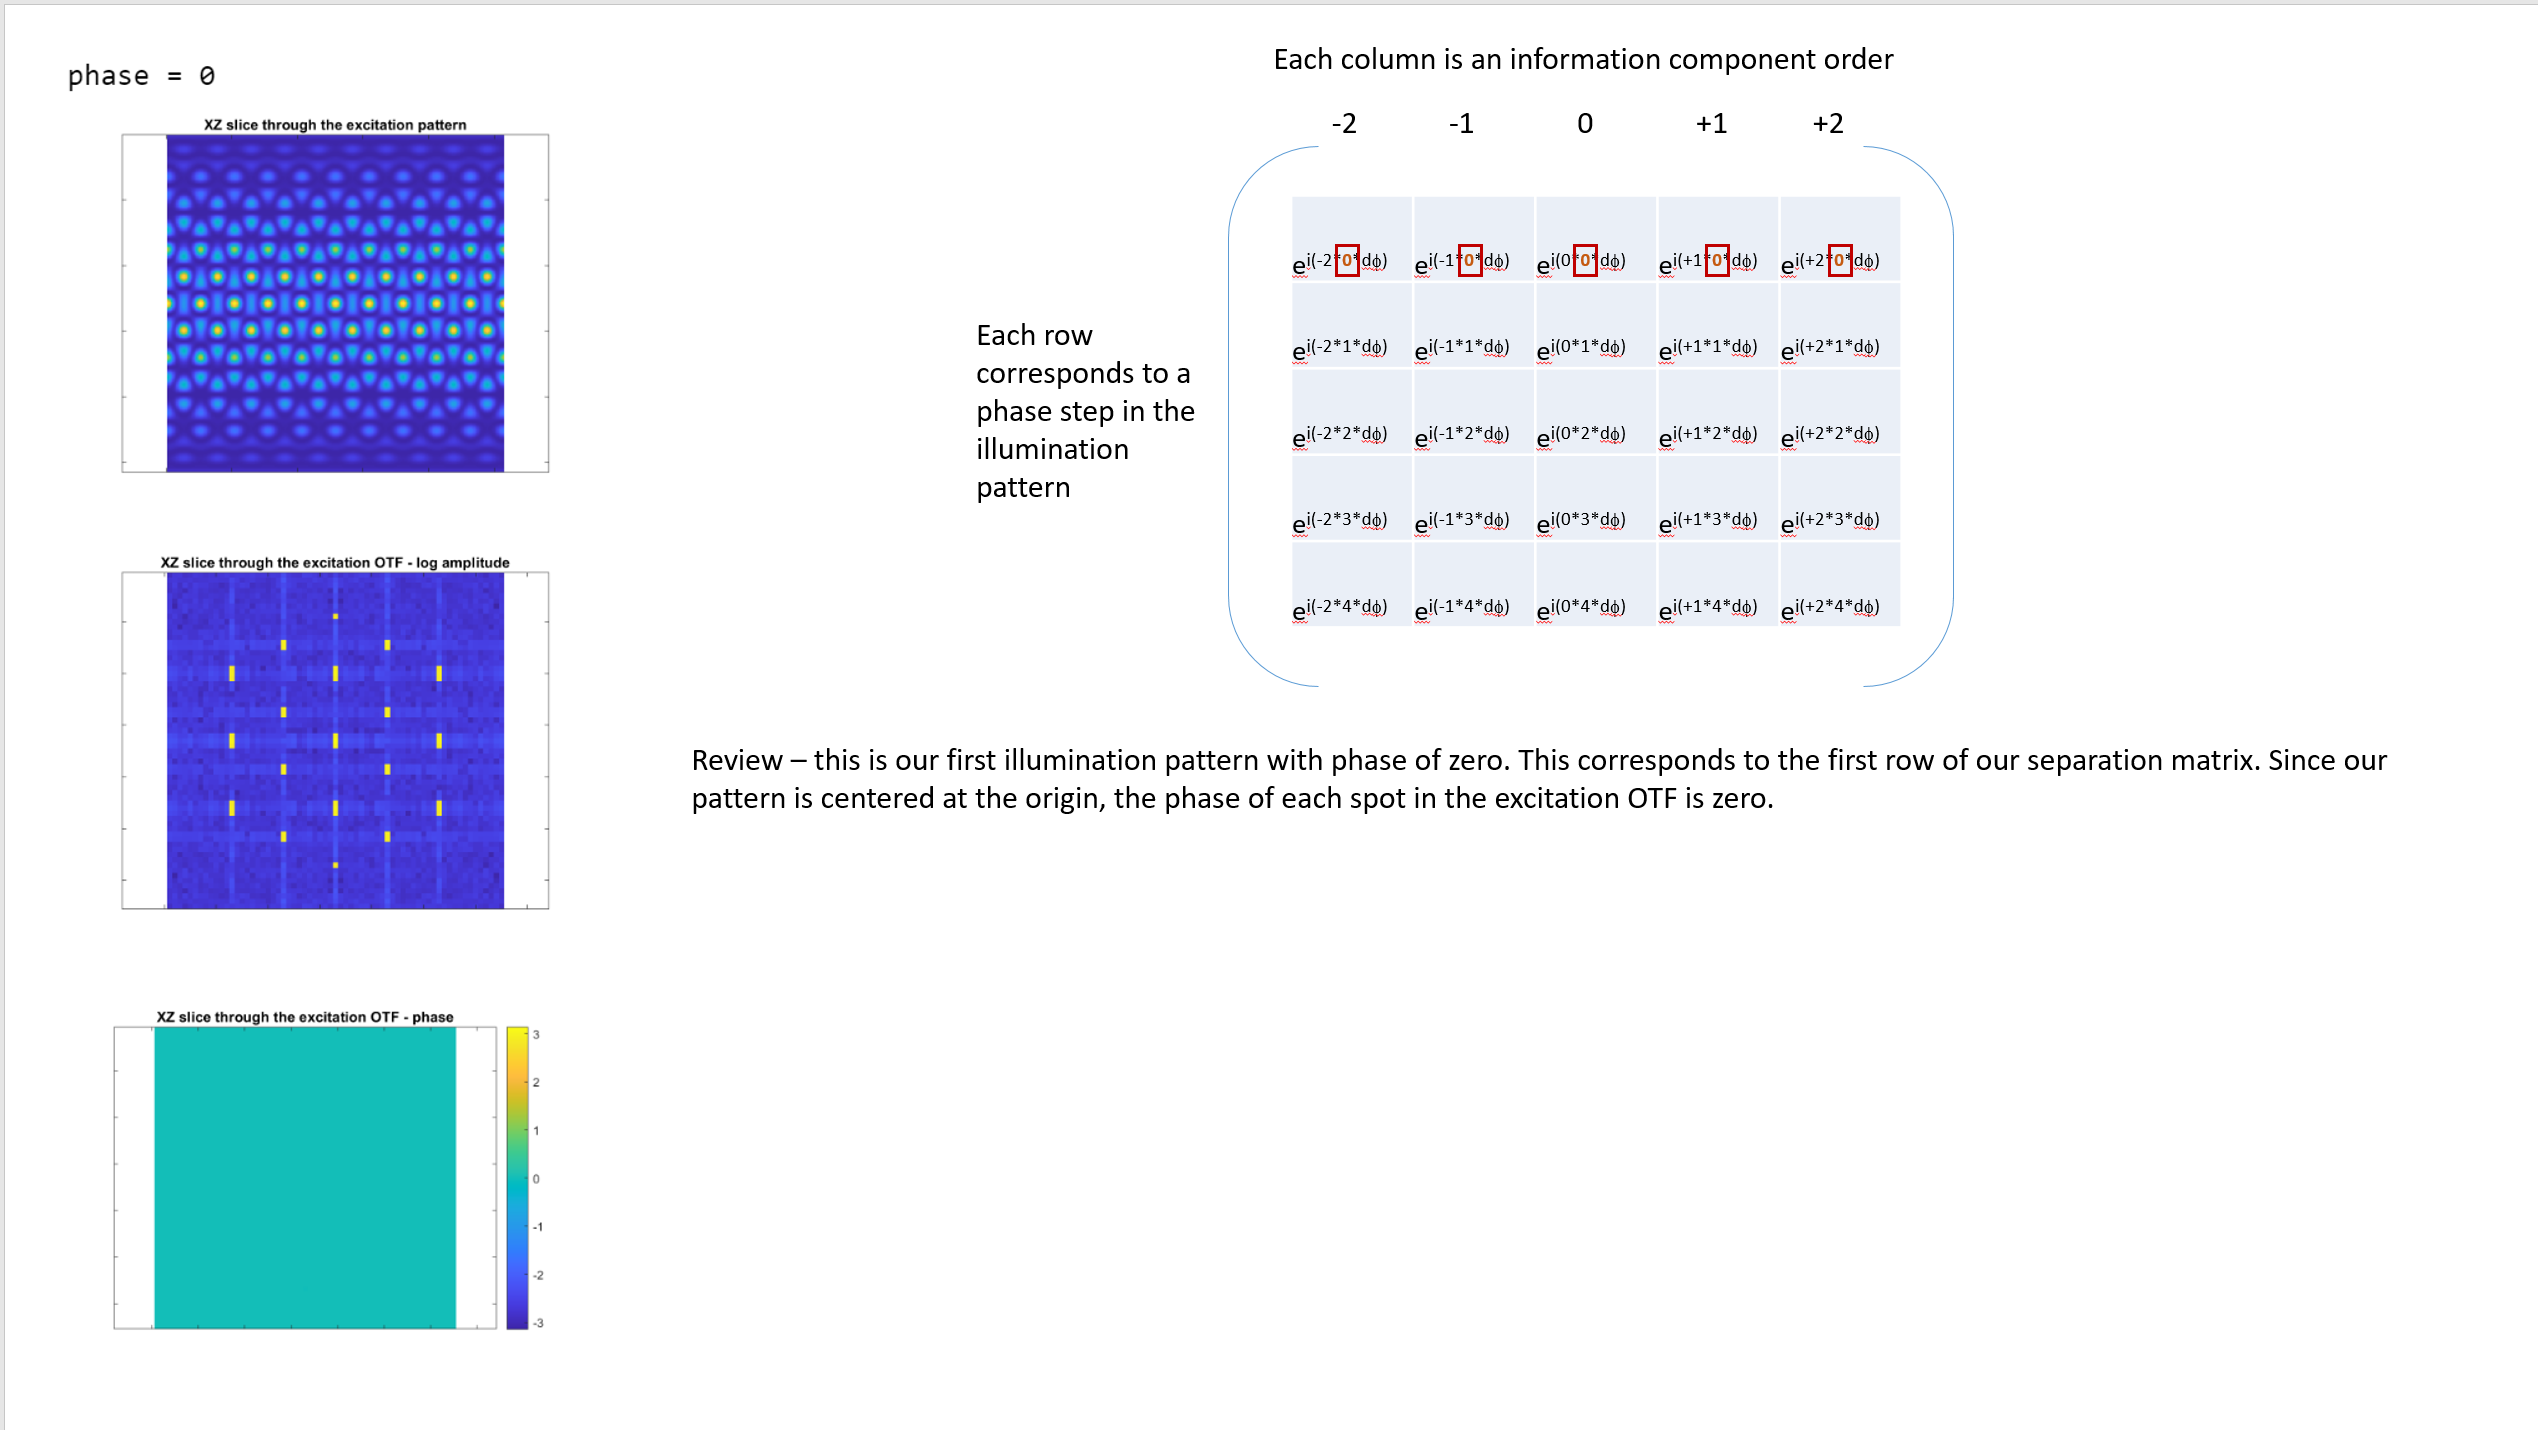

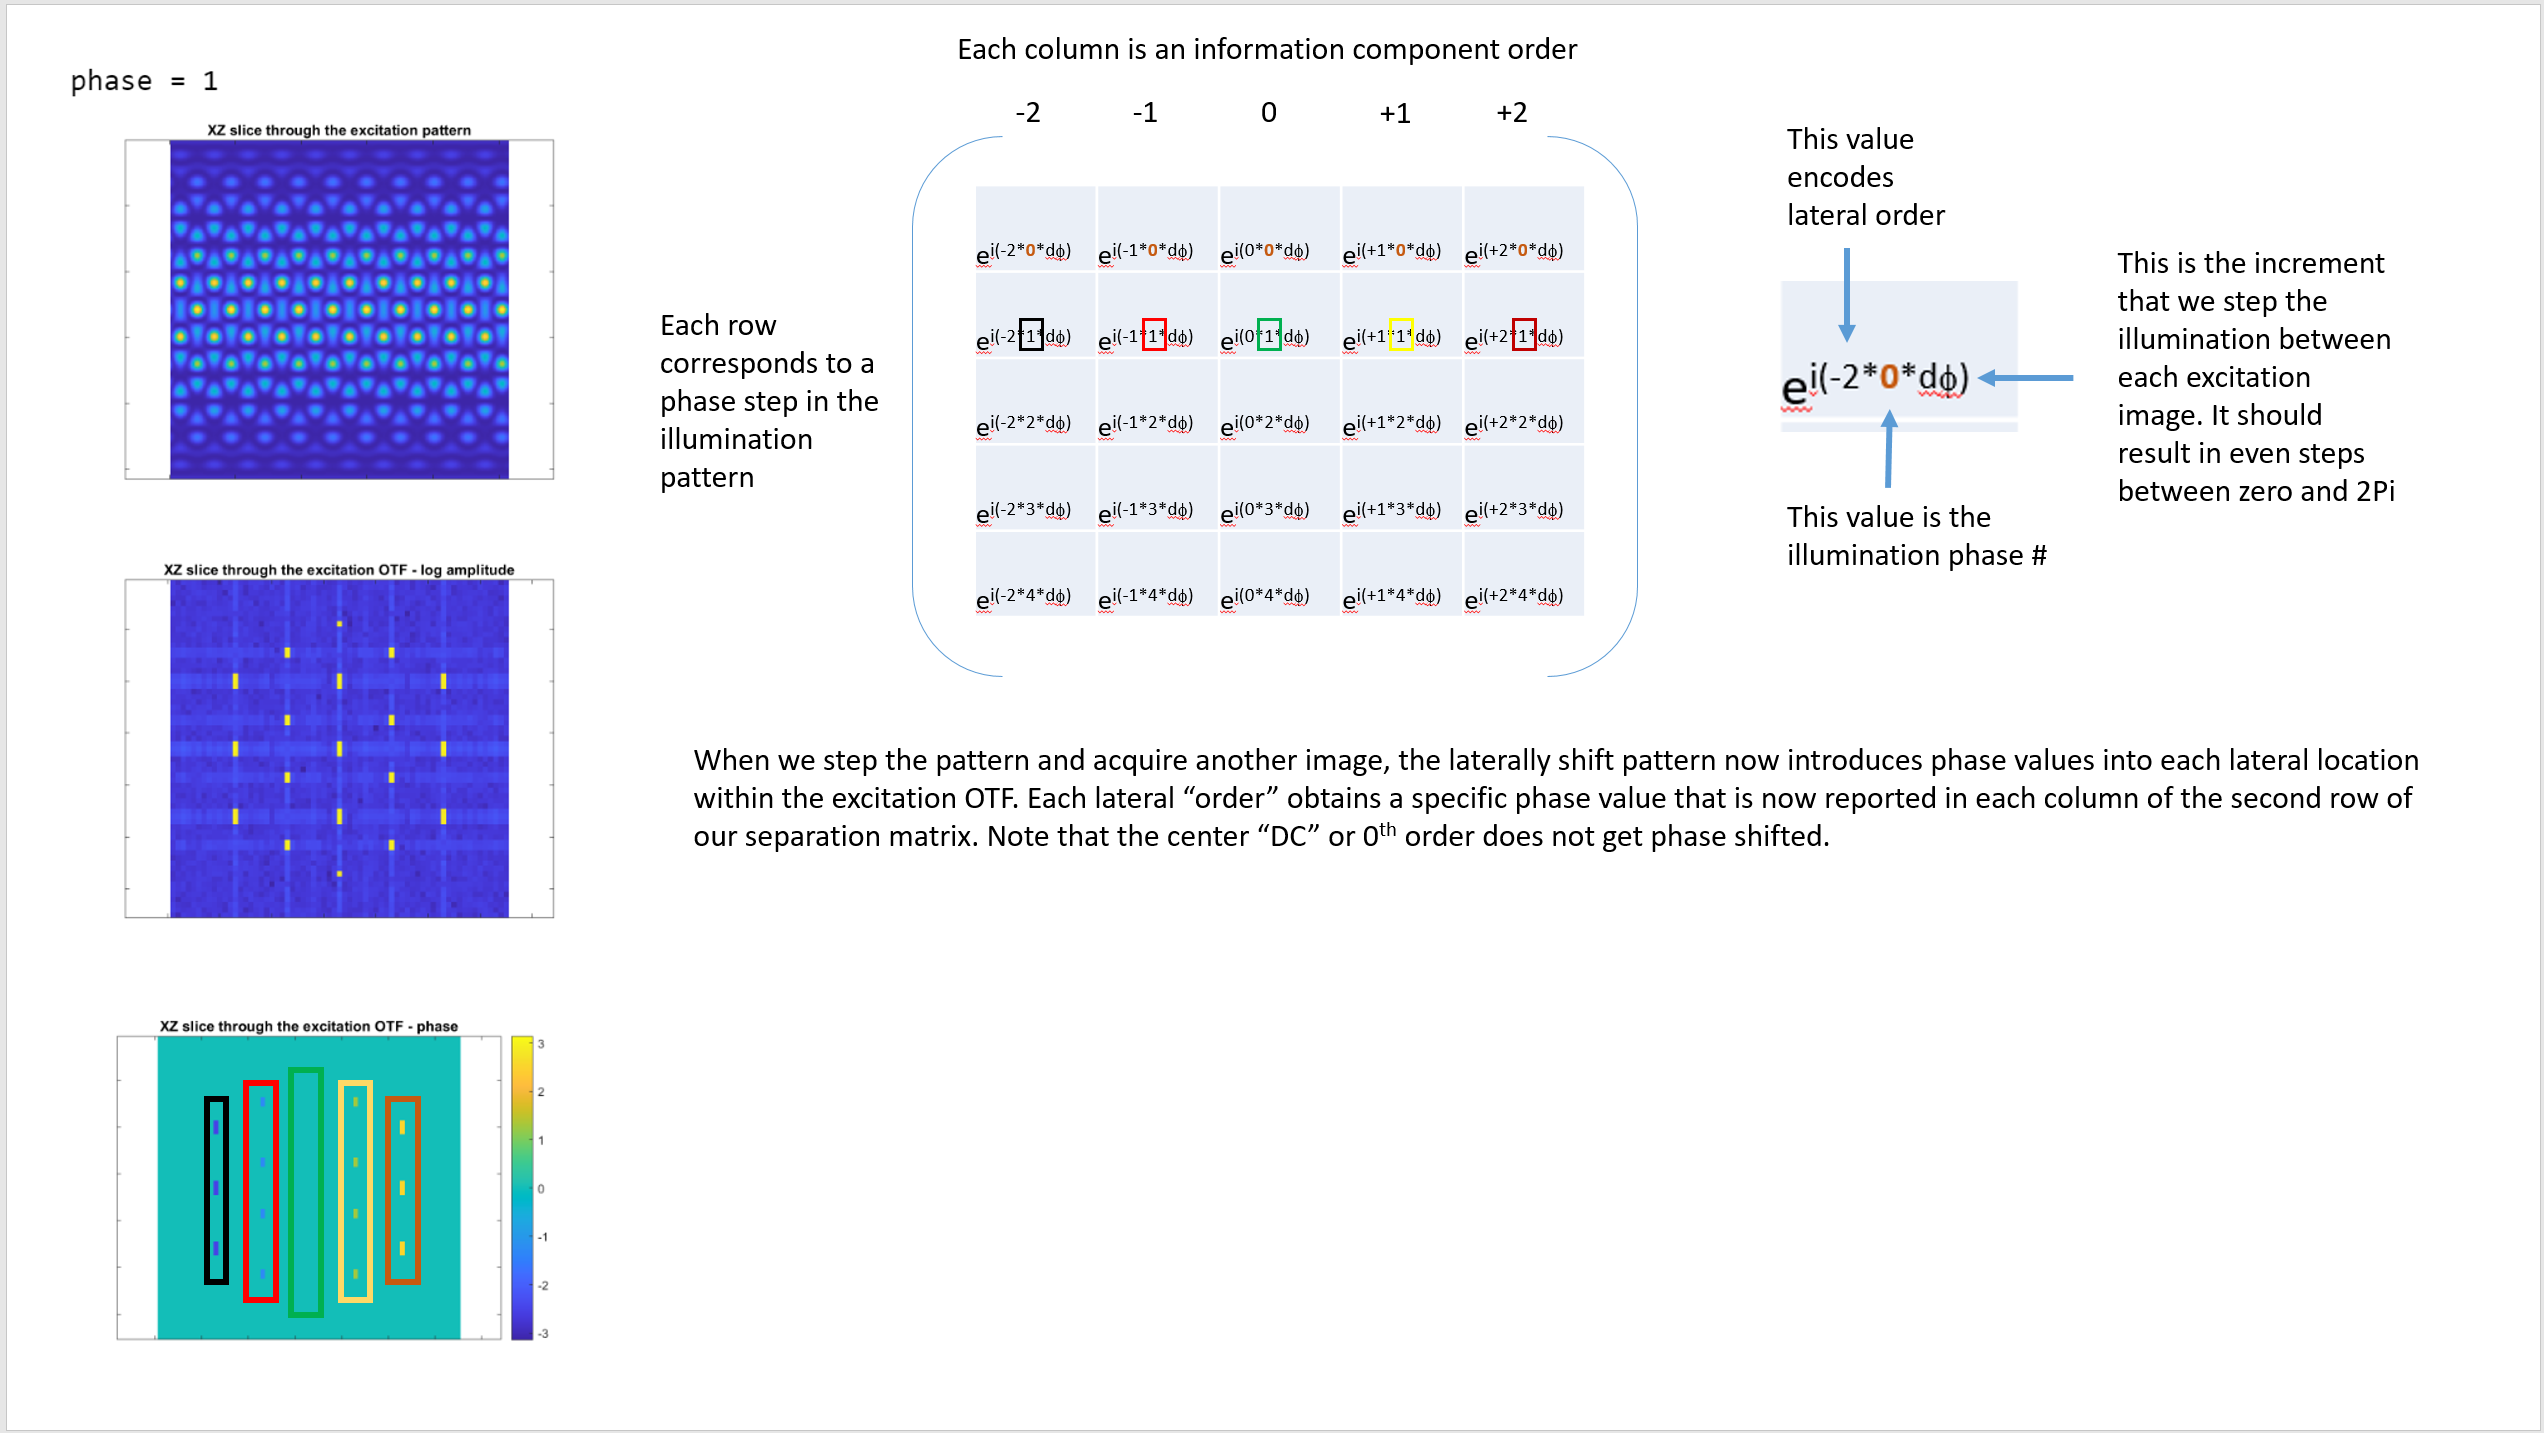

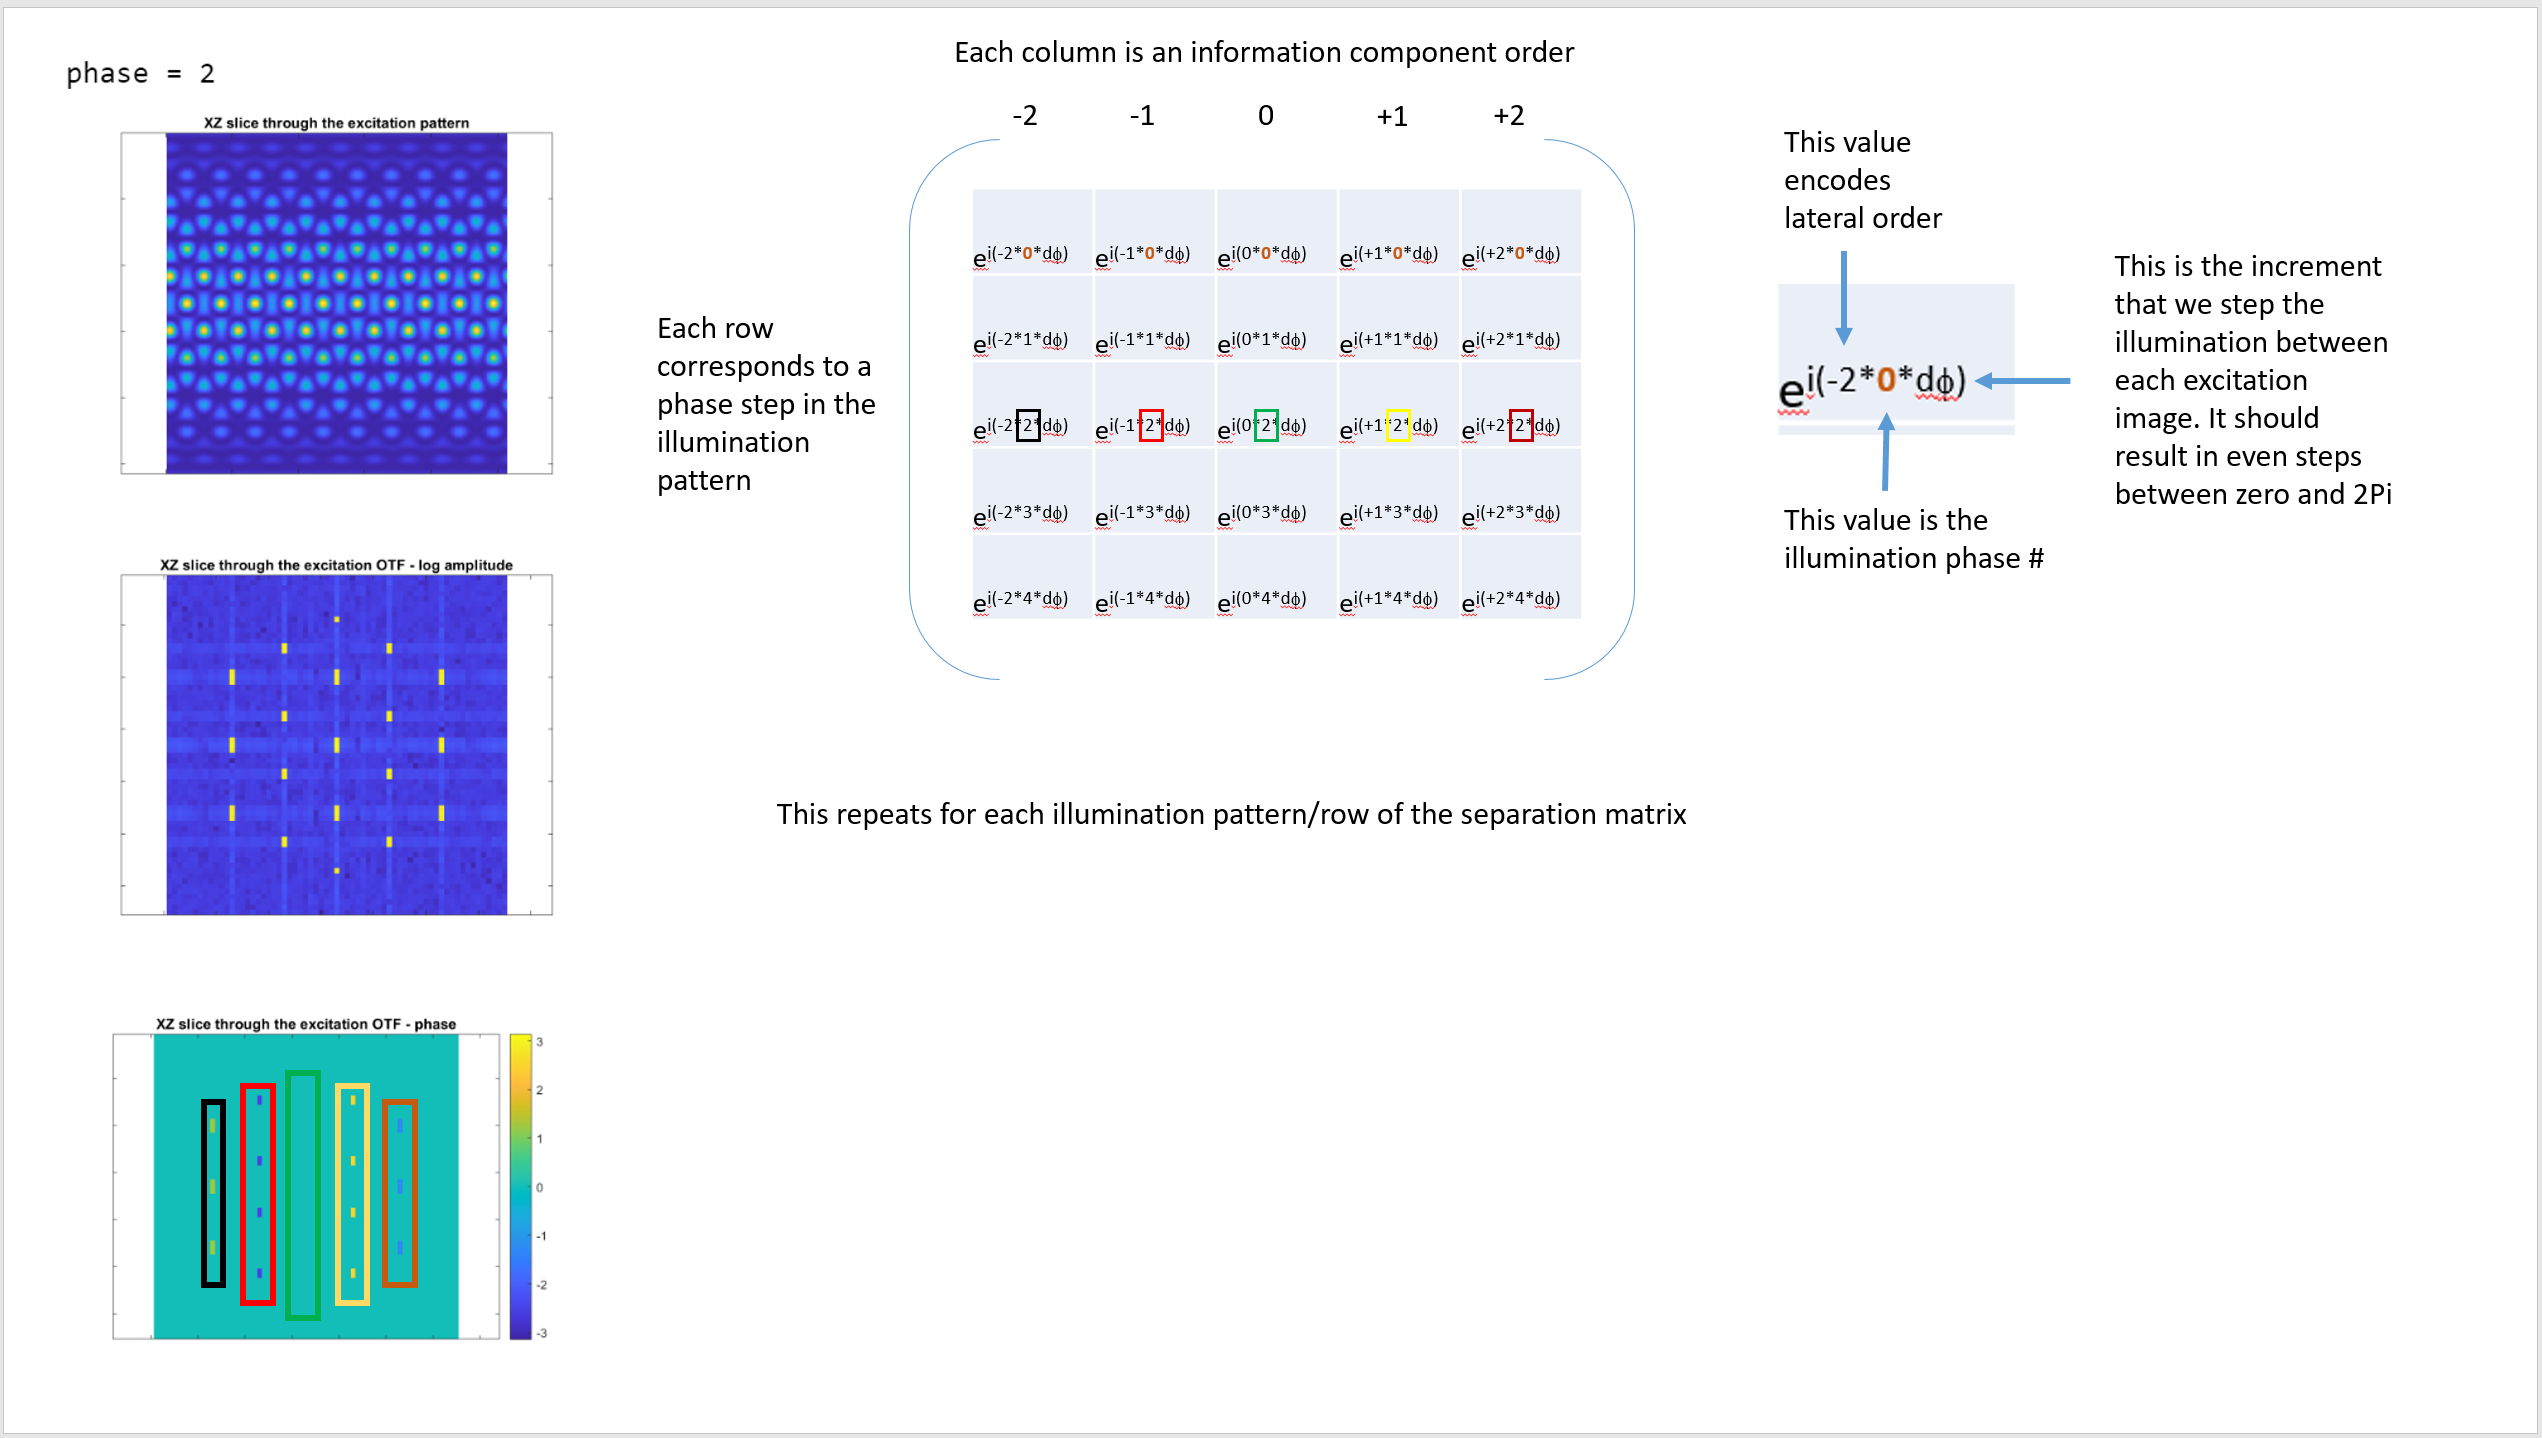

This implies that the individual information components can be obtained by inverting the separation matrix and then solving the linear system of equations for each pixel. Here, since our image was just a delta function, our recovered information components will be the OTF's for each order. Note also that in the process, we've assumed that the starting phase for our first illumination pattern is zero (i.e. the pattern is perfectly centered relative to our camera). In practice, this is not possible. However, precise control over the phase step d_phi is possible. Thus each element of the separation matrix may also have an offset corresponding to the starting phase of the pattern before we do our stepping. This is a parameter that is fit in the reconstruction software and one that we'll deal with later.

The code for this part looks like this:


['Separating information components']

ans = 'Separating information components'

%Make the forward separation matrix
[sep_matrix]=make_forward_separation_matrix(5,5);

%Make the inverse separation matrix
inv_sep_matrix=pinv(sep_matrix);

%Separate OTF orders by solving the linear system of equations for each pixel

O=zeros(nx,ny,nz,num_lat_order);

for ii=0:n_phases-1
    ii
    eval(['O(:,:,:,1)=O(:,:,:,1)+inv_sep_matrix(1,ii+1)*Dk_',num2str(ii),';']); %m2 order
    eval(['O(:,:,:,2)=O(:,:,:,2)+inv_sep_matrix(2,ii+1)*Dk_',num2str(ii),';']); %m1 order
    eval(['O(:,:,:,3)=O(:,:,:,3)+inv_sep_matrix(3,ii+1)*Dk_',num2str(ii),';']); %0th order
    eval(['O(:,:,:,4)=O(:,:,:,4)+inv_sep_matrix(4,ii+1)*Dk_',num2str(ii),';']); %p1 order
    eval(['O(:,:,:,5)=O(:,:,:,5)+inv_sep_matrix(5,ii+1)*Dk_',num2str(ii),';']); %p2 order
end

ii = 0

ii = 1

ii = 2

ii = 3

ii = 4


%Mask transfer functions based on their theoretical OTF support
tt=0;
for ii=(num_lat_order+1)/2:num_lat_order
    vert_comp=diff_vec_unique((ismember(diff_vec_unique(:,1:2),diff_vec_lateral(ii,:),'rows')),3)/dkx;
    mask=calc_OTF_extent(NA_det,nimm,wvl_em,nx,ny,nz,dx,dz,cat(2,zeros(length(vert_comp),2),vert_comp));
    O(:,:,:,ii)=O(:,:,:,ii).*mask;
    if tt~=0
        O(:,:,:,(num_lat_order+1)/2-tt)=O(:,:,:,(num_lat_order+1)/2-tt).*mask;
    end
    tt=tt+1
end

tt = 1

tt = 2

tt = 3

%Display the results for the overall Dr and Dk of the data
viewpoint = "XZ"

viewpoint = "XZ"

order = 3%Actually goes like 0, +1, -1, +2,-2, but the slider goes from 0-4

order = 3

%Stupid conditional so that I can title the graphs
if order == 0
    odr = '-2'
else if order == 1
        odr = '-1'
else if order == 2
        odr= '0'
else if order == 3
        odr = '+1'
else if order == 4
        odr = '+2'
end
end
end
end
end

odr = '+1'

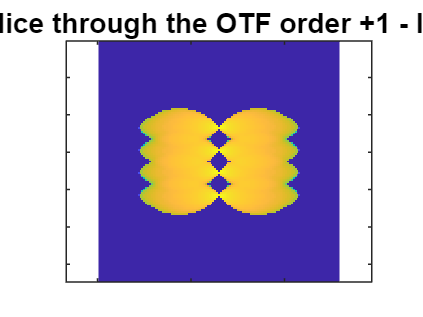


if viewpoint == 'XY'
    eval(['imagesc(imrotate(squeeze(log(abs(O((nx+1)/2-64:(nx+1)/2+64,(ny+1)/2-64:(ny+1)/2+64,(nz+1)/2,order+1)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title(['Center XY slice through the OTF order ',odr,' - log amplitude'])
    axis equal 
end
if viewpoint == 'XZ'
    eval(['imagesc(imrotate(squeeze(log(abs(O((nx+1)/2,(ny+1)/2-64:(ny+1)/2+64,(nz+1)/2-64:(nz+1)/2+64,order+1)))),90))']);
    set(gca,'YTickLabel',[])
    set(gca,'XTickLabel',[])
    title(['Center XY slice through the OTF order ',odr,' - log amplitude'])
    axis equal
end

These are now the OTF's for each information order. These will be used in the data reconstruction process. A future script will mirror this one for simulating the forward problem, but the data will not be a simple delta function. Simulating the forward problem and extracting the information components will be the same as what we've shown here. However, we'll also have to shift these information components back to their correct locations in frequency space, deconvolve out the contributions from each orders' OTF, and then inverse transform back into real space to recover the super-resolved image.